# **LAB 6 - CLUSTERING, PCA E GENE ONTOLOGY**

## **CLUSTERING**

*Import data for a time-course experiment (timedata.mat). Identify 16 distinct clusters using a hierarchical clustering:*

*• obtain 16 clusters with a hierarchical clustering strategy*

*• draw in the same matlab figure the 16 clusters obtained*

*Visualize the expression profiles (imagesc) before and after the reorganization provided by the clustering:*

*• draw the red-green image for the unordered data*

*• obtain the ordered list and the figure of the complete dendrogram*

*• draw the red-green image for the ordered data*

All'interno di `timedata `sono presenti:

- `genes` contiene i nomi dei geni

- `times` sono i valori in ore degli istanti di tempo della misurazione

- `yeastvalues` contiene i valori dell'espressione genica. I 614 geni (in riga) sono valutati sul microarray in 7 (colonne) istanti di tempo successivi. 

load('timedata.mat');

#### **Clustering gerarchico**

Ad ogni step si calcola la distanza tra tutti i geni e si raggruppano i due geni con associata la distanza minore. `pdist `calcola le **pairwise distances, **utilizzando la correlazione come metodo di distanza. Il numero di distanze calcolate è N*(N-1)/2 (la distanza per viene calcolata tra ognuno degli N geni ed il resto dei N-1 geni, eliminando quelle calcolate due volte).

corrdist = pdist(yeastvalues, 'corr');

Con la funzione `linkage `si accoppiano i geni con distanza ridotta, impostando i valori dei nuovi geni risultanti dall'accoppiamento come il valore medio dei due componenti. `clustertree `è una matrice (N-1)x3, contenente i geni nella coppia e la distanza tra loro

clustertree = linkage(corrdist,'average');

Per ricavare 16 cluster dagli N-1 accoppiamenti si usa `cluster,` che data una matrice che rappresenta la gerarchia (data in output dalla funzione `linkage`) e il numero di cluster richiesti, restituisce un vettore di N dove ad ogni posizione è assegnata la label del cluster.

cluster_labels = cluster(clustertree,'maxclust',16);

Plottiamo i valori dei geni in un grafico multiplo 4x4. In ogni subplot sono plottati i valori di espressione genica nel tempo riferiti ad ognuno dei 16 cluster: l'andamento dell'espressione è molto simile per i geni dello stesso cluster. 

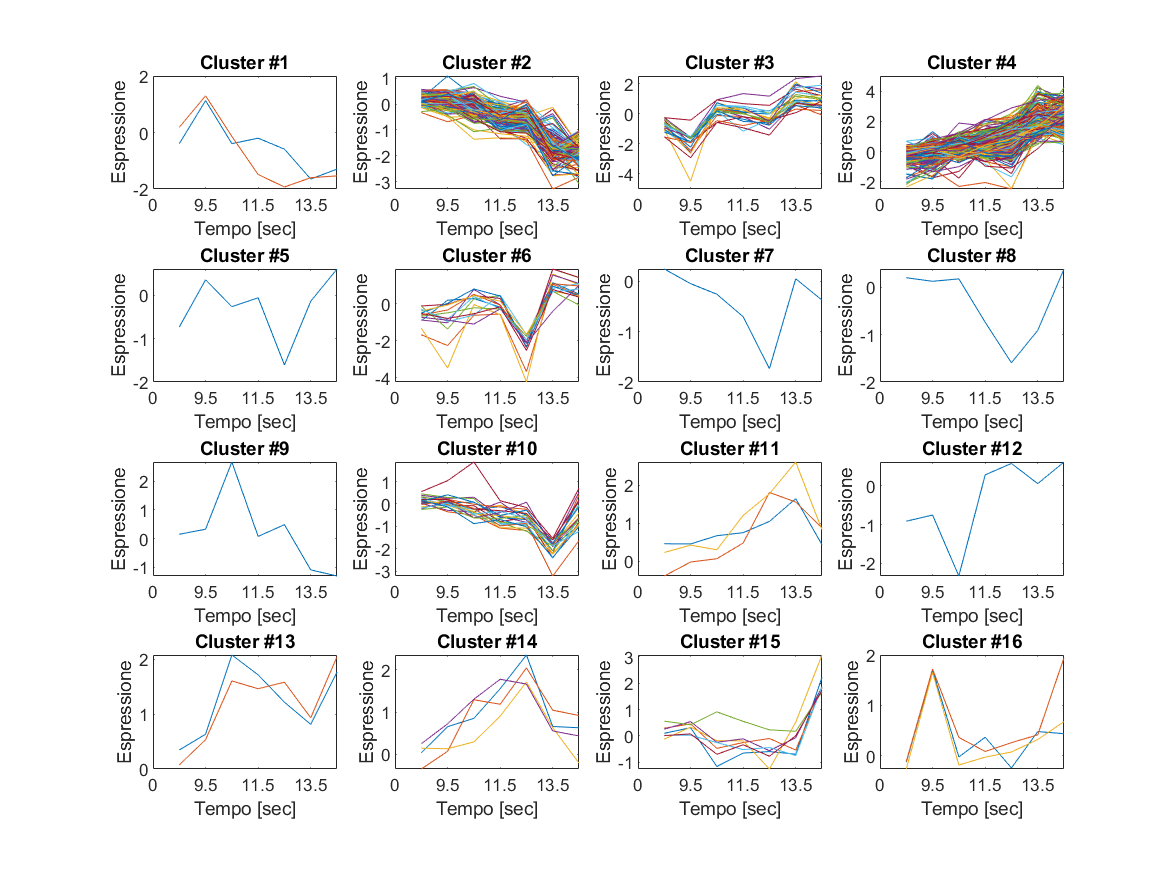

bigfigure;
for i = 1:16
    subplot(4,4,i);
    plot(yeastvalues(cluster_labels==i,:)');
    title(['Cluster #' num2str(i)]);
    xlabel('Tempo [sec]'); xticklabels(times); ylabel('Espressione');
end

In ogni cluster è visualizzata l'espressione genica, simile per i geni nello stesso cluster. 

Plottiamo il dendrogramma con `dendrogram, `che richiede il cluster tree ottenuto da linkage. 0 è impostato per plottare il dendrogramma intero. `dendrogram `produce il dendrogramma, e richiedendo il terzo output `perm` si ottengono gli indici delle permutazioni utlizzati per ordinare gerarchicamente il cluster. `perm `è un vettore riga di N elementi con N il numero dei geni, dove il k-esimo gene è associato all'indice che lo posiziona nella gerarchia 

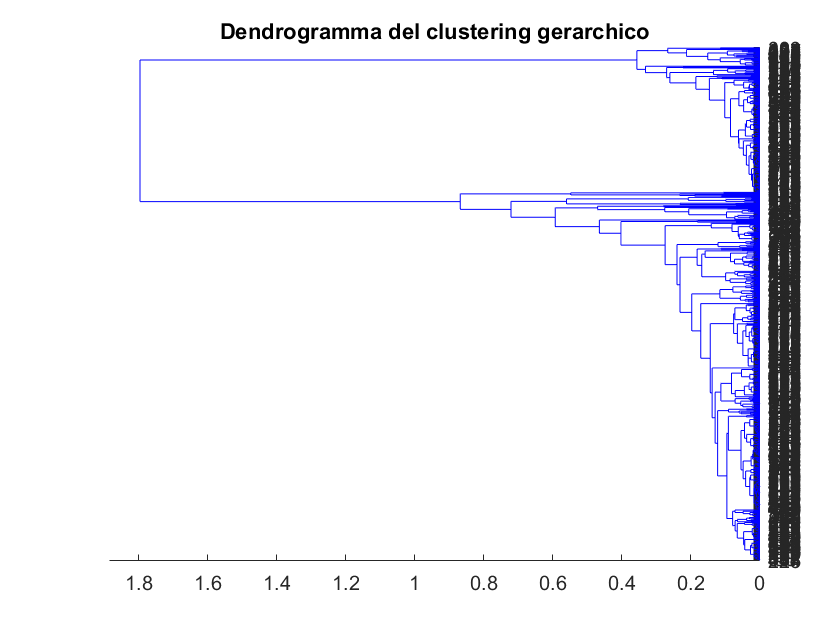

figure
[~,~,perm] = dendrogram(clustertree, 0, 'orient','left');
title('Dendrogramma del clustering gerarchico');

Visualizziamo la heatmap dell'espressione genica prima e dopo il clustering, così da poter visualizzare i geni ordinati in modo tale da raggruppare quelli con espressione simile

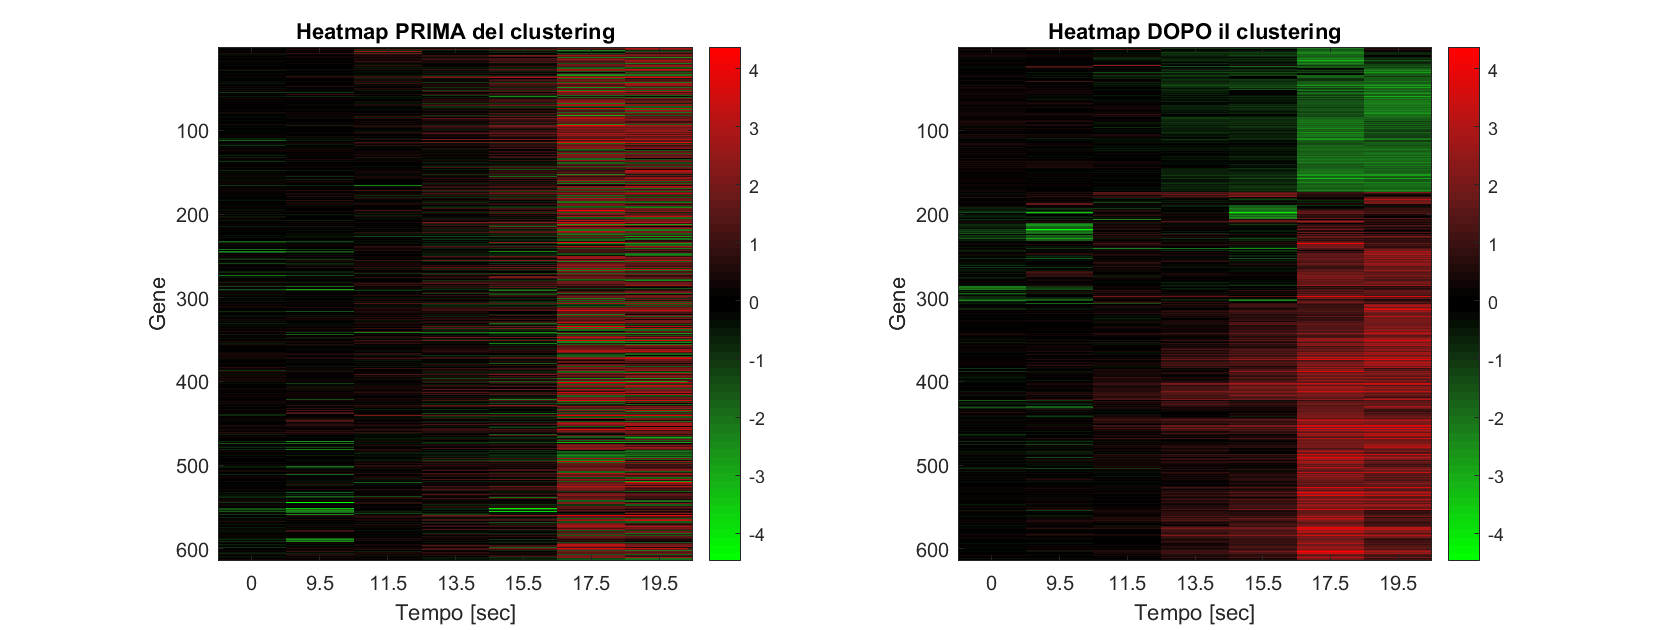

load("RedGreen_cmap.mat"); % Carichiamo la colormap RG
hhfigure; subplot(121); imagesc(flipud(yeastvalues)); colorbar; colormap(RedGreen_cmap)
title('Heatmap PRIMA del clustering'); xlabel('Tempo [sec]'); xticklabels(times); ylabel('Gene');
subplot(122); imagesc(flipud(yeastvalues(perm,:))); colorbar; colormap(RedGreen_cmap)
title('Heatmap DOPO il clustering'); xlabel('Tempo [sec]'); xticklabels(times); ylabel('Gene');

La funzione `clustergram `produce automaticamente il dendrogramma del clustering gerarchico e la heatmap dopo il clustering. Richiede in ingresso la matrice su cui operare il raggruppamento, con i seguenti parametri:

- `yeastvalues: `La matrice NxT (N numero di geni, T istanti di tempo);

- `'Cluster': `La dimensione su cui operare il clustering. Se la dimensione di clustering è quella delle colonne (`1`), si ottiene un raggruppamento per righe e viceversa. In questo caso si specificano le colonne perchè i geni sono identificati dalle righe 

- `'RowPDist': `Il metodo per il calcolo della distanza pair-wise tra le righe (se la dimensione di clustering fosse stata sulle righe era necessario specificare `'ColumnPDist'`). In questo caso si sceglie come distanza il valore di correlazione

- `'OptimalLeafOrder': `Flag per specificare l'ordinamento ottimale di foglie del dendrogramma (geni) simili. Non è un passaggio necessario, e richiede tempo computazionale e memoria soprattuto per datasets di grandi dimensioni come in questo caso.

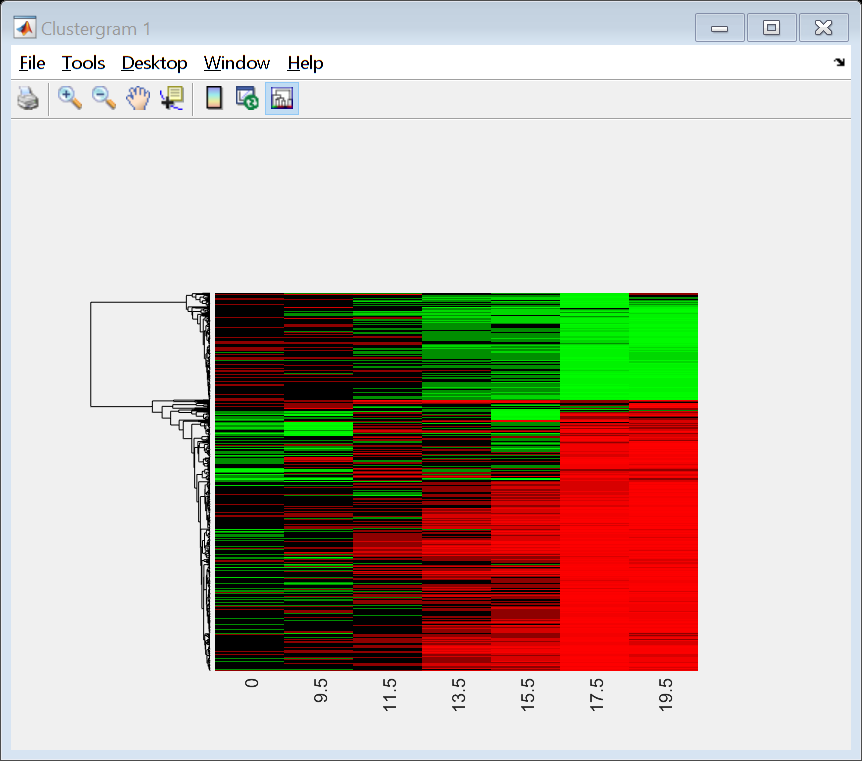

CG = clustergram(yeastvalues,'Cluster',1,'RowPDist','corr','OptimalLeafOrder','false');
set(CG, 'ColumnLabels',times); % Labels per le colonne = Istanti di tempo

## PCA - Principal Component Analysis

*Load the leukemia.mat file. The variable leukemia has 50 rows (genes) and 72 columns (patients). The variable cancertype is a cell array of strings containing the diagnosis labels.*

*Visualize the dataset by means of a projection onto the first three PCs.*

*• find the covariance matrix*

*• transform the data*

*• compute the percentage of variance explained (with three PCs)*

*• do the samples segregate consistently with the diagnosis?*

load("leukemia.mat");

- `cancertype` contiene le labels per il tipo di cancro dei 72 pazienti. E' un vettore colonna 72x1 con il label ALL o AML

- `geneinfo` contiene le informazioni dei 50 geni analizzati. E' una matrice 51x2 con la prima riga di intestazione, la prima colonna con il tipo di gene e la seconda colonna con il codice identificativo del gene 

- `leukemia` contiene l'espressione dei 50 geni sui 72 pazienti. E' una matrice 50x72

Trasponiamo la matrice in modo da ottenere i geni sulle colonne e i pazienti sulle righe.

leukemia = leukemia';

La media di ogni gene viene sottratta ad ogni paziente, in modo da eliminare il bias non biologicamente significativo.

leukemia_norm = leukemia - repmat(mean(leukemia),72,1);

Si ricava la matrice di covarianze `covmat `e se ne calcolano autovalori e autovettori. `covmat `è una matrice 50x50, riferita alla covarianza dei 50 geni espressi sui pazienti. Gli autovalori in output dalla funzione `eig `sono in ordine crescente e ugualmente sono disposti i relativi autovalori. Per la PCA l'ordinamento necessario è quello decrescente, che otteniamo con `flipud `per il vettore di autovalori e con `fliprl `per la matrice di autovettori.

covmat = cov(leukemia_norm); 
[eigvec, eigval] = eig(covmat);
eigval = flipud(diag(eigval));
eigvec = fliplr(eigvec)

eigvec =    -0.1157   -0.0358    0.0032   -0.2358    0.1604    0.1017    0.0885   -0.1837   -0.1385    0.2143    0.2302   -0.1446    0.0792    0.0262   -0.0720   -0.1541   -0.3347    0.1523   -0.5862    0.2377   -0.1091    0.2059    0.1019    0.1558    0.0540   -0.0995    0.0599    0.0079   -0.0139    0.0620    0.0405    0.0171   -0.0591   -0.0383    0.0492    0.0176    0.0496   -0.0808    0.0648   -0.0526    0.0222   -0.0050    0.0531    0.0253   -0.0174    0.0018   -0.0090    0.0188    0.0312    0.0349
   -0.1317    0.0471    0.0337   -0.3004    0.1881    0.0302    0.1184    0.1756   -0.2877    0.0049    0.0413   -0.0771   -0.1253   -0.1409    0.0966    0.4834    0.2107   -0.2355   -0.0113   -0.1114   -0.2007    0.3981   -0.1920   -0.1537    0.0641   -0.0204    0.1307    0.0578   -0.0343    0.0359   -0.0485   -0.0091    0.1129   -0.0917   -0.0226   -0.0056   -0.0770    0.0345    0.0388    0.0268   -0.0017    0.0641   -0.0157    0.0318   -0.0203    0.0065    0.0044   -0.0021   -0.0225

Effettuiamo la trasformazione delle coordinate come prodotto tra la matrice dei dati (normalizzata con la rimozione del bias) e la matrice di autovettori riordinata.

proj_leuk = leukemia_norm*eigvec;

Plottiamo ora la percentuale di varianza spiegata da ogni autovalori. Da questo grafico è possibile riconoscere **quali delle 50 dimensioni di interesse spiegano la maggior parte della varianza. **La percentuale di varianza spiegata dalla *k-esima *dimensione del sistema di riferimento è definita come     $Var_k = \frac{\sum_{i=1}^{k}{\lambda_i}}{\sum_{k=1}^{N}{\lambda_k}}$

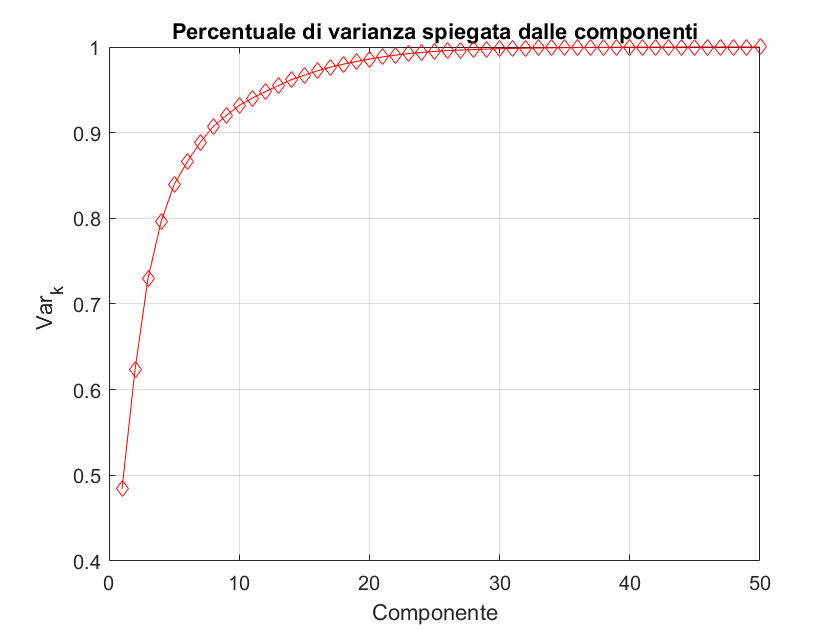

figure; plot(cumsum(eigval)/sum(eigval),'d-r');
title('Percentuale di varianza spiegata dalle componenti');
xlabel('Componente');
ylabel('Var_k ')
grid on

Si nota dal grafico che la maggior parte (circa il 100%) della varianza dei dati è spiegata dalle prime 20 dimensioni circa; possiamo quindi scartare il resto delle componenti. Per poterle plottare in uno scatterplot, manteniamo solamente le prime 3 dimensioni.

Estraiamo gli indici dei pazienti ALL e AML con `strmatch, `in modo da poterli plottare con colori diversi e valutare il livello di raggruppamento

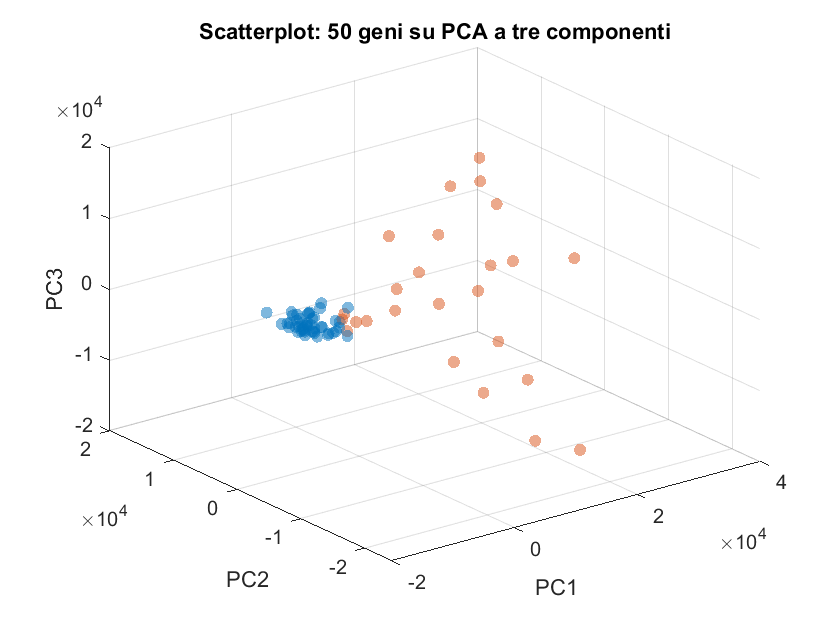

ALL_idx = strmatch('ALL',cancertype);
AML_idx = strmatch('AML',cancertype);
figure;
scatter3(proj_leuk(ALL_idx,1), proj_leuk(ALL_idx,2), proj_leuk(ALL_idx,3),...
    'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
hold on
scatter3(proj_leuk(AML_idx,1), proj_leuk(AML_idx,2), proj_leuk(AML_idx,3),...
    'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
xlabel('PC1'); ylabel('PC2'); zlabel('PC3');
title('Scatterplot: 50 geni su PCA a tre componenti')

## GENE ONTOLOGY

*Explore relationships between Gene Ontology terms and, given a specific term, retrieve its parents in the graph (less specific terms).*

*• Load the Gene Ontology database into a MATLAB object using the geneont function*

*• Visualize the ancestors of the term 'ribosome' (GOID:5840)*

*Given the list of genes in selection.txt, perform enrichment analysis at the website http://llama.mshri.on.ca/funcassociate/*

*Search for the found terms at the AmiGO website: *[http://amigo.geneontology.org/amigo.](http://amigo.geneontology.org/amigo.)

GeneOntology è caricabile nello workspace MATLAB con la funzione `geneont`, che richiede il parametro `'Live' = 'true'` per caricare l'ultima versione aggiornata del database. `geneont `produce la handle `GO `da cui è possibile accedere alle entries del database

GO = geneont('LIVE','true')

Gene Ontology object with 47218 Terms.


Con `get `si ottengono i parametri della handle a GeneOntology

get(GO);

                 default_namespace: 'gene_ontology'
                    format_version: '1.2'
                      data_version: 'releases/2020-11-18'
                           version: ''
                              date: ''
                          saved_by: ''
                 auto_generated_by: ''
                         subsetdef: {17×1 cell}
                            import: ''
                    synonymtypedef: 'systematic_synonym "Systematic synonym" EXACT'
                           idspace: ''
    default_relationship_id_prefix: ''
                        id_mapping: ''
                            remark: ''
                           typeref: ''
                  unrecognized_tag: {'ontology'  'go'}
                             Terms: [47218×1 geneont.term]



L'indicizzazione `GO(5840) `restituisce la handle all'5840esimo elemento di GeneOntology, i cui parametri possono venire ottenuti richiedendo il campo `terms`

GO(5840).terms

            id: 5840
          name: 'ribosome'
      ontology: 'cellular component'
    definition: '"An intracellular organelle, about 200 A in diameter, consisting of RNA and protein. It is the site of protein biosynthesis resulting from translation of messenger RNA (mRNA). It consists of two subunits, one large and one small, each containing only protein and RNA. Both the ribosome and its subunits are characterized by their sedimentation coefficients, expressed in Svedberg units (symbol: S). Hence, the prokaryotic ribosome (70S) comprises a large (50S) subunit and a small (30S) subunit, while the eukaryotic ribosome (80S) comprises a large (60S) subunit and a small (40S) subunit. Two sites on the ribosomal large subunit are involved in translation, namely the aminoacyl site (A site) and peptidyl site (P site). Ribosomes from prokaryotes, eukaryotes, mitochondria, and chloroplasts have characteristically distinct ribosomal proteins." [ISBN:0198506732]'
       comment: ''
       syno

Il campo `is_a `di `terms` contiene gli indici dei parents della entry specificata. Richiedendo poi il campo `terms `del parent si ottiengono le informazioni del parent. In questo caso ***ribosome ***viene identificato come ***intracellular non-membrane-bounded organelle****.*

parent_idx = GO(5840).terms.is_a

parent_idx = 43232

GO(parent_idx).terms

            id: 43232
          name: 'intracellular non-membrane-bounded organelle'
      ontology: 'cellular component'
    definition: '"Organized structure of distinctive morphology and function, not bounded by a lipid bilayer membrane and occurring within the cell. Includes ribosomes, the cytoskeleton and chromosomes." [GOC:go_curators]'
       comment: ''
       synonym: {'synonym'  '"intracellular non-membrane-enclosed organelle" EXACT []'}
          is_a: [2×1 double]
       part_of: 5622
      obsolete: 0



Visualizziamo tutto l'albero di ancestors del ribosoma. Attraverso `getancestors `si ricavano gli indici di GeneOntology della sequenza di parents che conducono a *ribosome*. `ancestors` contiene quindi la handle a queste 8 entries separatamente

ancestors = GO(getancestors(GO, 5840))

Gene Ontology object with 8 Terms.


`getmatrix `riceve in input gli indici delle entries e produce una matrice sparsa `relmat` che indica le associazioni parent-child delle suddette entries. Questa matrice viene data in input a `biograph, `che produce un oggetto visualizzabile con `view. `A `biograph `vengono anche dati i nomi delle entries che devono essere visualizzati sullo schema

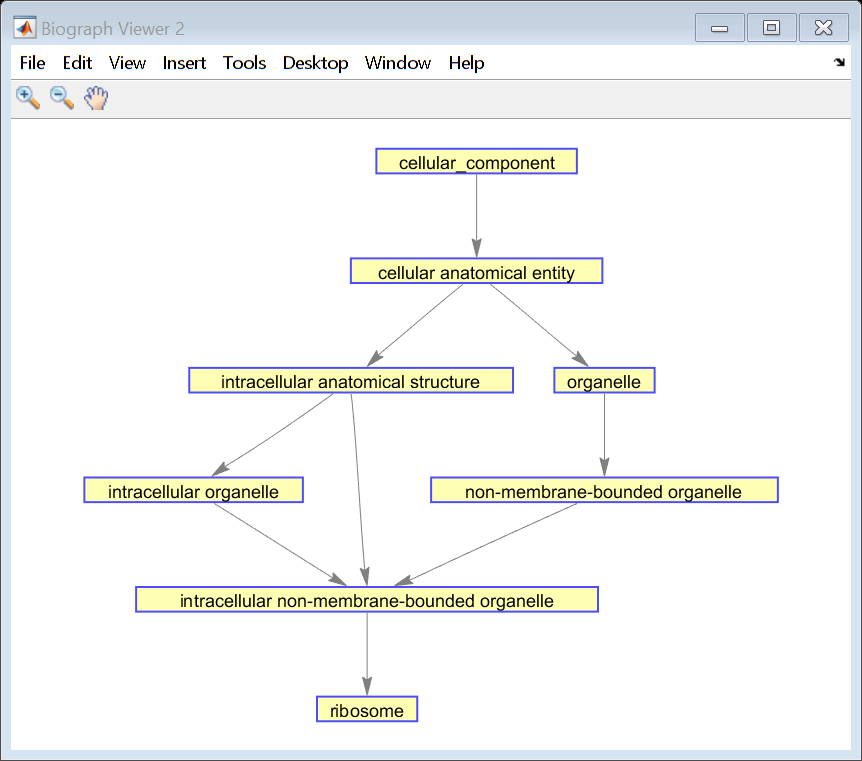

relmat = getmatrix(ancestors);
BG = biograph(relmat, get(ancestors.Terms, 'name'));
view(BG);